# Vehicle Fuel Efficiency

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The file "fuelEconomy2.txt" contains fuel economy data for different models of cars. This file is open so that you can examine its contents.

In this exercise, you will import a subset of data and group the MPG (miles per gallon) values based on the number of cylinders and find the average MPG for each group. Finally, you will create a bar plot and customize it to look like the plot shown below:

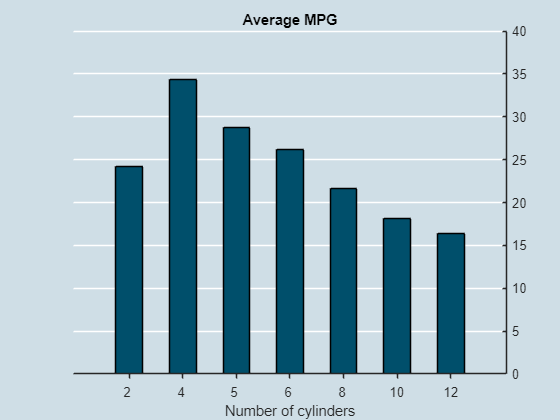

dat = datastore("./data/fuelEconomy2.txt");
dat.ReadSize = 362;
data = dat.read;
[gNum,gVal] = findgroups(data.NumCyl);
avgMPG = splitapply(@mean, data.CombinedMPG, gNum);
b = bar(avgMPG);
xlabel("Number of cylinders")
title("Average MPG")
f = gcf;
a = gca;
f.Color = [0.81 0.87 0.9];
a.Color = [0.81 0.87 0.9];
a.Box = "off";
a.YAxisLocation = "right";
a.YGrid = "on";
a.GridColor = [1 1 1];
a.GridAlpha = 1;
a.XTickLabel = gVal;
a.YLim = [0 40];
ax = a.XAxis;
ax.TickDirection = "out";
b.FaceColor = [0, 0.31, 0.42];
b.BarWidth = 0.5;